# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Explore and Organize Image Dataset 

Your goal in this step is to define defect classes and labels (keep it small).

- Load and inspect the images and labels from your chosen dataset (see the project page on GitHub for recommended datasets) to understand the part types, defect classes, and data balance

- Store labels in a table loaded by `readtable(...)`

- Manage images and labels with `imageDatastore(...)` and the `Labels` property (or use the example workflow for setting up labeled image datastores).

- Helpful reference: [Create and Explore Datastore for Image Classification](https://www.mathworks.com/help/deeplearning/ug/create-and-explore-datastore-for-image-classification.html).

- Choose 2-3 defect types (for FAIL) plus PASS

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

% The following creates a table, which can be saved in a separate file
rawData = "change to whatever directory you have here";

imds = imageDatastore(rawData, IncludeSubfolders=true);

% Store text of file names in array
files = string(imds.Files);
elem = numel(files);

parts = strings(elem, 1);
condition = strings(elem, 1);
defectType = strings(elem, 1);


for k = 1:elem
    % Goes through the directory each time and splits objects based on
    % filename
    folderNames = split(files(k), filesep);

    idx = length(folderNames);

    % Assigns label to each image based on folder type
    if folderNames(idx-1) == "PASS"
        parts(k) = folderNames(idx-2);
        condition(k) = "PASS";
        defectType(k) = "NONE";
    else
        parts(k) = folderNames(idx-3);
        condition(k) = "FAIL";
        defectType(k) = folderNames(idx-1);
    end
end


dataSetTable = table(files, categorical(parts), categorical(condition),...
    categorical(defectType), 'VariableNames', {'Filename', 'Part', 'Part Condition', 'Defect Type'})

## Task 2: Build a Single-Image Inspection Function

Your goal in this step is to create a function that analyzes an image to identify and quantify suspected defects detected in the image. You're trying to answer the question: "What in the image looks suspicious?"

To build this function you will need to:

**STEP 1. Standardize the images**

- Read images with `imread(...)` or through `imageDatastore(...)`.

- Standardize size with `imresize(...)` so metrics and model input are consistent.

- Convert to grayscale with `rgb2gray(...)` as needed (e.g. classical processing may rely on intensity values)

**STEP 2. Preprocess the images**

- Apply classical preprocessing, prioritizing stability over complexity. In other words, apply only what you need to reduce sensitivity to normal station variation. Suggested processing includes:

- Lighting correction: `imflatfield(...)` (or background estimate with `imgaussfilt(...)` and subtraction)

- Contrast normalization: `adapthisteq(...)`

- Denoising: `medfilt2(...)` or `imgaussfilt(...)`

- Save intermediate results during development (e.g., `imshowpair(...)`) for quick debugging.

**STEP 3. *****Optionally*****, define a region of interest (ROI)**

If each image already contains a centered part with minimal clutter, skip ROI and use the full image:

- `roi = I;`

If needed, define ROI fully automatically (no per-image manual selection), by using, for example:

- Fixed crop defined once (camera is consistent): indexing or `imcrop(...) `OR

- Auto-crop from the part mask: segment the part, compute `BoundingBox` using `regionprops(...)`, then `imcrop(...)`.

**STEP 4. Segment the image for an evidence overlay**

Your goal is to generate an evidence overlay and a few measurable numbers—not a perfect segmentation. Generate a simple binary mask that highlights suspicious regions in the image. Use a defect-appropriate recipe and keep it short:

- Start with thresholding: `imbinarize(...)` or `adaptthresh(...)` + `imbinarize(...)`

- Clean small specks: `bwareaopen(...)`

- Bridge gaps (if appropriate): `imclose(...)`

- Fill holes (only when it matches your goal (e.g., for a clean outer part silhouette): `imfill(...,'holes')`

Deliverable: `maskEvidence = defectEvidence(roi)`

**STEP 5. Extract a small set of interpretable metrics**

Your goal is to quantify the evidence for suspected defects, which supports traceability and debugging in your workflow. These metrics should answer the question: “What did the algorithm see, and how strong was the evidence?”

These measurements are mainly for traceability (inspection logs), debugging, and sanity checks. Keep it to 3–4 metrics so it stays easy.

Recommended minimal metrics (works for many defect types):

- `numComponents`: how many separate suspicious regions were found (use `bwconncomp(maskEvidence)` and read `NumObjects`)

- `maxArea`: size of the largest suspicious region (use `regionprops(maskEvidence,'Area')`)

- `areaRatio`: fraction of the ROI flagged as suspicious (`nnz(maskEvidence) / numel(maskEvidence)`)

- *(optional)* `edgeDensity`: if your evidence comes from edges (chips/scratches), measure how “edgy” the ROI is (`nnz(edgeMask) / numel(edgeMask)`)

**STEP 6. *****Optionally*****, implement a rule-based baseline.**

Implement 2–3 conservative rules so your system can always produce an explainable fallback decision mechanism. This can also be a useful comparison with AI result.

- Example: fail if `maxArea > Amax` or `numComponents > Nmax`

Deliverable: `baselineDecision = decideRules(evidence)`

## `Introduction`

`The purpose of the single-image inspection functions is to identify and highlight suspected defect regions in individual manufacturing images. Different image-processing methods and metrics were evaluated to determine an effective approach for separating defect regions from the normal features of each part. Because the appearance and defect characteristics vary between part types, a separate inspection function was created for each part and stored in its corresponding .m file. Each function produces a binary evidence mask, a red evidence overlay, and interpretable metrics describing the detected regions.`

# `Molly`

## `inspectHazelnut.m Function`

`The inspectHazelnut function standardizes each image to 224 x 224 pixels, converts it to grayscale, and applies mild Gaussian denoising. A fixed region of interest is used to focus on the hazelnut because it originally occupied only part of the full image. Cropping will reduce background interference and allow the segmentation to focus more closely on the hazelnut. Because the defects have different appearances, separate segmentation branches are used: crack and hole_hazel are treated as dark defects, while cut and print are treated as bright defects. Adaptive thresholding and morphological operations are used to reduce normal texture, exclude the outer shell boundary, and connect disconnected defect regions. The final evidence mask is displayed as a red overlay and used to calculate the number of suspicious regions, largest region area, and area ratio.`

`The hazelnut inspection function identified suspicious regions for all four defect types. Depending on the image, a crack could be detected as one continuous region, or as several separated regions. The hole and cut evidence also produced multiple highlighted areas, some of which may be false detections caused by shell texture or the hazelnut border. Overall, the segmentation program successfully highlighted the main defect regions, although some false detections remained.`

`One challenge was selecting morphological operations that worked well across multiple dark hazelnut defect types. I tested imfill, but decided not to include it in the dark-defect segmentation branch because it tended to overfill the detected regions and overfill the hole defect. This caused the evidence mask to become too large and less representative of the actual defect.`

`Another challenge was developing the segmentation branch for the cut and print defects. The initial thresholding method repeatedly highlighted the outer border of the hazelnut instead of only the defect. To reduce this false detection, a rough mask of the hazelnut was created and eroded to define a smaller inner region. This excluded most of the outer shell boundary and allowed the final evidence mask to focus more closely on the actual defect.`

`Two different segmentation branches were necessary because one thresholding method did not reliably detect both dark and bright defects. The crop dimensions, threshold sensitivities, and morphological settings were adjusted using sample images from each hazelnut defect category to improve defect detection while reducing false detections from the shell texture and the object outline.`

## `inspectBottle.m Function`

`The inspectBottle function standardizes each image to 224 x 224 pixels, converts it to grayscale, and applies mild Gaussian denoising. Because the bottle is centered against a plain background, the full image is used as the region of interest. A circular ring mask is then created to limit the analysis to the bottle-rim area, where the broken defects are located. Local standard deviation is used to highlight areas with greater intensity variation, since damaged regions were expected to appear more irregular than smoother, undamaged areas. Adaptive thresholding and morphological operations are then used to create the evidence mask and connect nearby suspicious regions.`

`The bottle inspection function detected suspicious regions in both the broken-large and broken-small images. However, a lot of the inner bottle rim was also highlighted because its strong edges, reflections, and texture produced intensity variation similar to the actual broken areas. As a result, the size and number of highlighted regions varied between images. The evidence metrics were useful for describing the generated mask, but they did not consistently represent the true defect size. Overall, the bottle was the most difficult part to segment because the damaged areas had texture and edge characteristics similar to the normal rim.`

`The challenge for the bottle images was separating the broken defect from the normal inner rim. The stdfilt method successfully detected irregular texture, but it also responded strongly to the rim’s natural edges and reflections. A fixed ring mask reduced detections outside the expected defect area, but it could not fully distinguish the broken region from the normal rim. This demonstrates a limitation of using texture-based thresholding alone for the bottle images.`

## `inspectWood.m Function`

`The inspectWood function standardizes each image to 224 × 224 pixels. Because the wood surface fills the image, the full image is used as the region of interest. The RGB image is converted to Lab color space, which separates lightness from color information. The lightness channel contains one brightness value per pixel, so it can be displayed and processed as a grayscale intensity image. This channel is used instead of rgb2gray because it isolates brightness while reducing the influence of the wood’s natural brown color variation. The lightness values are then scaled from 0 to 1 and mildly smoothed to reduce small wood-grain fluctuations and noise. Focusing on lightness allows MATLAB to search for areas that appear unusually dark or bright compared with the surrounding wood surface.`

`Separate segmentation branches are used because the wood defects have different appearances. The hole_wood and liquid defects are treated as dark regions, while scratches are treated as bright regions. Adaptive thresholding finds areas that are darker or brighter than the wood around them. Morphological opening is then used to reduce long wood-grain responses, area filtering removes small isolated regions, and morphological closing connects nearby fragments that may belong to the same defect.`

`The wood inspection function detected the main defect regions in the hole, liquid, and scratch examples. The hole images produced the best overall results because the evidence masks focused mainly on the actual defect regions. Morphological opening was especially helpful for the hole defects because it removed most of the long vertical wood-grain responses that were falsely highlighted. A few false detections were still present, but they were less noticeable than those in the liquid and scratch images. As a result, the hole images generally produced fewer suspicious regions. The liquid and scratch images were more difficult because many natural wood-grain patterns were also highlighted, increasing both the number and size of the detected regions.`

`One challenge was selecting threshold values that could detect both thin and thick scratches. Threshold settings that worked well for thicker scratches sometimes failed to detect thinner scratches. Therefore, a middle-ground value was selected so the function could identify most scratch defects, although some thin scratches were still missed.`

`Another challenge was separating actual defects from the natural grain pattern. The grain contains long bright and dark lines that can resemble liquid streaks or scratches. Using separate dark- and bright-defect branches improved the results, but the scratch images still produced many false detections from normal grain lines. This shows that intensity-based thresholding alone cannot always distinguish defects from normal wood texture. Overall, the function usually located the main suspicious areas, but the liquid and scratch masks still contained noticeable false detections, and some parts of the actual defects were not always highlighted.`

clear;
clc;
close all;

% -------------------------------------------------------------------- HAZELNUT --------------------------------------------------------------------------------------

% NOTE: hz = hazelnut

% Use the Import Data Live Tasks below to select one image from each hazelnut defect category.
% The imported variables should be named: hz_crackImg, hz_holeImg, hz_cutImg, and hz_printImg.


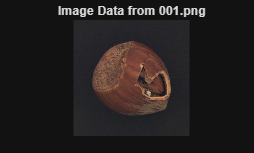

% Import image
hz_crackImg = imread(".\mvtec_anomaly_detection_USED_v4\hazelnut\FAIL\crack\001.png");

% Display results
imshow(hz_crackImg);
title("Image Data from 001.png");

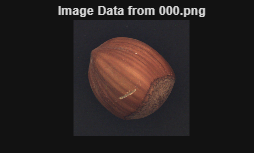

% Import image
hz_cutImg = imread(".\mvtec_anomaly_detection_USED_v4\hazelnut\FAIL\cut\000.png");

% Display results
imshow(hz_cutImg);
title("Image Data from 000.png");

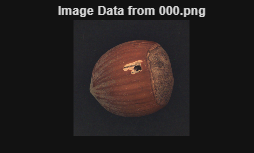

% Import image
hz_holeImg = imread(".\mvtec_anomaly_detection_USED_v4\hazelnut\FAIL\hole_hazel\000.png");

% Display results
imshow(hz_holeImg);
title("Image Data from 000.png");

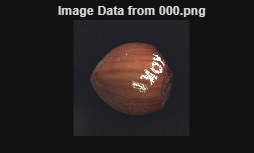

% Import image
hz_printImg = imread(".\mvtec_anomaly_detection_USED_v4\hazelnut\FAIL\print\000.png");

% Display results
imshow(hz_printImg);
title("Image Data from 000.png");

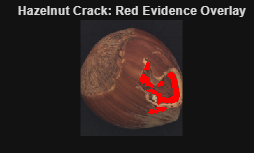


% Pass each defect label so the function selects the appropriate dark- or bright-defect segmentation branch.
[hz_crackMask, hz_crackEvidence, hz_crackROI, hz_crackROIRGB, hz_crackOverlay] = inspectHazelnut(hz_crackImg, "crack");
[hz_holeMask, hz_holeEvidence, hz_holeROI, hz_holeROIRGB, hz_holeOverlay] = inspectHazelnut(hz_holeImg, "hole_hazel");

[hz_cutMask, hz_cutEvidence, hz_cutROI, hz_cutROIRGB, hz_cutOverlay] = inspectHazelnut(hz_cutImg, "cut");
[hz_printMask, hz_printEvidence, hz_printROI, hz_printROIRGB, hz_printOverlay] = inspectHazelnut(hz_printImg, "print");

% Crack overlay.
figure;
imshow(hz_crackOverlay);
title("Hazelnut Crack: Red Evidence Overlay");

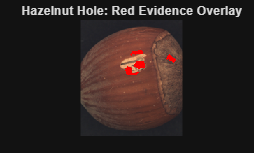


% Hole overlay.
figure;
imshow(hz_holeOverlay);
title("Hazelnut Hole: Red Evidence Overlay");

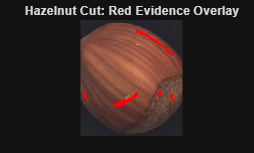


% Cut overlay.Hazelnut crack metrics:
figure;
imshow(hz_cutOverlay);
title("Hazelnut Cut: Red Evidence Overlay");

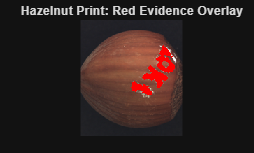


% Print overlay.
figure;
imshow(hz_printOverlay);
title("Hazelnut Print: Red Evidence Overlay");


% Interpretable metrics for crack, hole, cut, & print:

fprintf("\nHazelnut crack metrics:\n");


Hazelnut crack metrics:


fprintf("Number of suspicious regions: %d\n", hz_crackEvidence.numComponents);

Number of suspicious regions: 4


fprintf("Size of largest suspicious region: %d pixels\n", hz_crackEvidence.maxArea);

Size of largest suspicious region: 962 pixels


fprintf("Area ratio: %.4f\n", hz_crackEvidence.areaRatio);

Area ratio: 0.0515



fprintf("\nHazelnut hole metrics:\n");


Hazelnut hole metrics:


fprintf("Number of suspicious regions: %d\n", hz_holeEvidence.numComponents);

Number of suspicious regions: 4


fprintf("Size of largest suspicious region: %d pixels\n", hz_holeEvidence.maxArea);

Size of largest suspicious region: 145 pixels


fprintf("Area ratio: %.4f\n", hz_holeEvidence.areaRatio);

Area ratio: 0.0179



fprintf("\nHazelnut cut metrics:\n");


Hazelnut cut metrics:


fprintf("Number of suspicious regions: %d\n", hz_cutEvidence.numComponents);

Number of suspicious regions: 5


fprintf("Size of largest suspicious region: %d pixels\n", hz_cutEvidence.maxArea);

Size of largest suspicious region: 211 pixels


fprintf("Area ratio: %.4f\n", hz_cutEvidence.areaRatio);

Area ratio: 0.0220



fprintf("\nHazelnut print metrics:\n");


Hazelnut print metrics:


fprintf("Number of suspicious regions: %d\n", hz_printEvidence.numComponents);

Number of suspicious regions: 3


fprintf("Size of largest suspicious region: %d pixels\n", hz_printEvidence.maxArea);

Size of largest suspicious region: 536 pixels


fprintf("Area ratio: %.4f\n", hz_printEvidence.areaRatio);

Area ratio: 0.0555


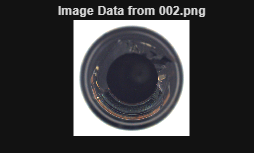

clear;
clc;
close all;

% -------------------------------------------------------------------- BOTTLE --------------------------------------------------------------------------------------


% NOTE: bo = bottle

% Use the Import Data Live Tasks below to select one image from each bottle defect category.
% The imported variables should be named: bo_largeImg and bo_smallImg.

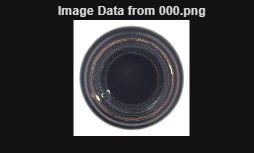

% Import image
bo_largeImg = imread(".\mvtec_anomaly_detection_USED_v4\bottle\FAIL\broken_large\002.png");


% Display results
imshow(bo_largeImg);
title("Image Data from 002.png");

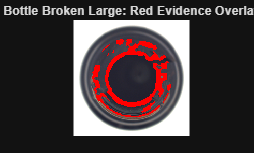

% Import image
bo_smallImg = imread(".\mvtec_anomaly_detection_USED_v4\bottle\FAIL\broken_small\000.png");

% Display results

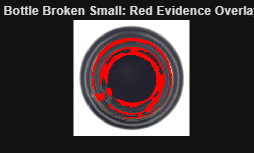

imshow(bo_smallImg);
title("Image Data from 000.png");

% Apply the same bottle inspection function to both bottle defect types.
[bo_largeMask, bo_largeEvidence, bo_largeROI, bo_largeROIRGB, bo_largeOverlay] = inspectBottle(bo_largeImg);

[bo_smallMask, bo_smallEvidence, bo_smallROI, bo_smallROIRGB, bo_smallOverlay] = inspectBottle(bo_smallImg);



Bottle broken_large metrics:


% Broken_large overlay.

Number of suspicious regions: 8


figure;

Size of largest suspicious region: 3889 pixels


imshow(bo_largeOverlay);

Area ratio: 0.1107


title("Bottle Broken Large: Red Evidence Overlay");



Bottle broken_small metrics:


% Broken_small overlay.

Number of suspicious regions: 5


figure;

Size of largest suspicious region: 4007 pixels


imshow(bo_smallOverlay);

Area ratio: 0.1175


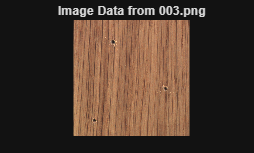

title("Bottle Broken Small: Red Evidence Overlay");

fprintf("\nBottle broken_large metrics:\n");
fprintf("Number of suspicious regions: %d\n", bo_largeEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", bo_largeEvidence.maxArea);
fprintf("Area ratio: %.4f\n", bo_largeEvidence.areaRatio);

fprintf("\nBottle broken_small metrics:\n");
fprintf("Number of suspicious regions: %d\n", bo_smallEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", bo_smallEvidence.maxArea);
fprintf("Area ratio: %.4f\n", bo_smallEvidence.areaRatio);

% -------------------------------------------------------------------- WOOD --------------------------------------------------------------------------------------


% NOTE: wo = wood

% Use the Import Data Live Tasks below to select one image from each wood defect category.
% The imported variables should be named: wo_holeImg, wo_liquidImg, and wo_scratchImg.

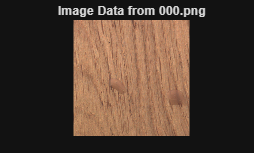

% Import image
wo_holeImg = imread(".\mvtec_anomaly_detection_USED_v4\wood\FAIL\hole_wood\003.png");


% Display results
imshow(wo_holeImg);
title("Image Data from 003.png");

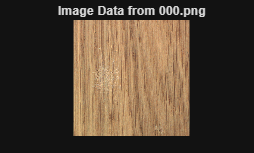

% Import image
wo_liquidImg = imread(".\mvtec_anomaly_detection_USED_v4\wood\FAIL\liquid\000.png");


% Display results
imshow(wo_liquidImg);
title("Image Data from 000.png");

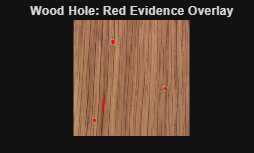

% Import image
wo_scratchImg = imread(".\mvtec_anomaly_detection_USED_v4\wood\FAIL\scratch\000.png");

% Display results
imshow(wo_scratchImg);
title("Image Data from 000.png");

% Pass each defect label so the function selects the appropriate dark- or bright-defect segmentation branch.

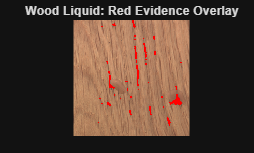

[wo_holeMask, wo_holeEvidence, wo_holeROI, wo_holeROIRGB, wo_holeOverlay] = inspectWood(wo_holeImg, "hole_wood");
[wo_liquidMask, wo_liquidEvidence, wo_liquidROI, wo_liquidROIRGB, wo_liquidOverlay] = inspectWood(wo_liquidImg, "liquid");

[wo_scratchMask, wo_scratchEvidence, wo_scratchROI, wo_scratchROIRGB, wo_scratchOverlay] = inspectWood(wo_scratchImg, "scratch");


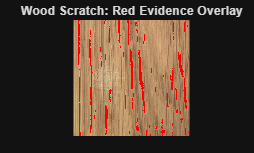

% Hole overlay.
figure;
imshow(wo_holeOverlay);
title("Wood Hole: Red Evidence Overlay");


% Liquid overlay.
figure;


Wood hole metrics:


imshow(wo_liquidOverlay);

Number of suspicious regions: 4


title("Wood Liquid: Red Evidence Overlay");

Size of largest suspicious region: 79 pixels


Area ratio: 0.0030


% Scratch overlay.
figure;


Wood liquid metrics:


imshow(wo_scratchOverlay);

Number of suspicious regions: 37


title("Wood Scratch: Red Evidence Overlay");

Size of largest suspicious region: 255 pixels


Area ratio: 0.0251


fprintf("\nWood hole metrics:\n");
fprintf("Number of suspicious regions: %d\n", wo_holeEvidence.numComponents);


Wood scratch metrics:


fprintf("Size of largest suspicious region: %d pixels\n", wo_holeEvidence.maxArea);

Number of suspicious regions: 54


fprintf("Area ratio: %.4f\n", wo_holeEvidence.areaRatio);

Size of largest suspicious region: 534 pixels


Area ratio: 0.0795


fprintf("\nWood liquid metrics:\n");
fprintf("Number of suspicious regions: %d\n", wo_liquidEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", wo_liquidEvidence.maxArea);
fprintf("Area ratio: %.4f\n", wo_liquidEvidence.areaRatio);

fprintf("\nWood scratch metrics:\n");
fprintf("Number of suspicious regions: %d\n", wo_scratchEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", wo_scratchEvidence.maxArea);
fprintf("Area ratio: %.4f\n", wo_scratchEvidence.areaRatio);


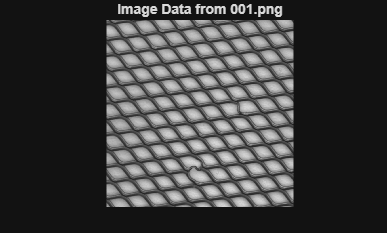

clear;
clc;
close all;

% -------------------------------------------------------------------- Grid --------------------------------------------------------------------------------------


% Use the Import Data Live Tasks below to select one image from each grid defect category.
% The imported variables should be named: gr_bentImg, gr_brokenImg, gr_glueImg, gr_metalContImg, gr_threadImg.

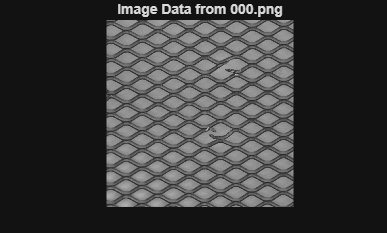

% Import image
gr_bentImg = imread(".\mvtec_anomaly_detection_USED_v4\grid\FAIL\bent\001.png");


% Display results
imshow(gr_bentImg);
title("Image Data from 001.png");

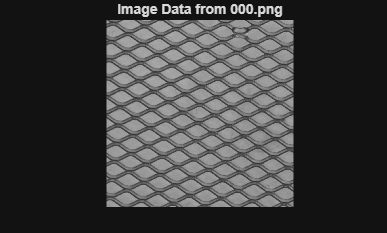

% Import image
gr_brokenImg = imread(".\mvtec_anomaly_detection_USED_v4\grid\FAIL\broken\000.png");


% Display results
imshow(gr_brokenImg);
title("Image Data from 000.png");

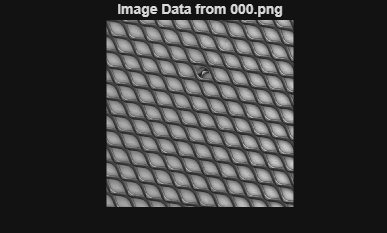

% Import image
gr_glueImg = imread(".\mvtec_anomaly_detection_USED_v4\grid\FAIL\glue\000.png");


% Display results
imshow(gr_glueImg);
title("Image Data from 000.png");

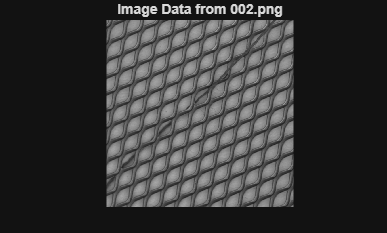

% Import image
gr_metalContImg = imread(".\mvtec_anomaly_detection_USED_v4\grid\FAIL\metal_contamination\000.png");


% Display results
imshow(gr_metalContImg);
title("Image Data from 000.png");

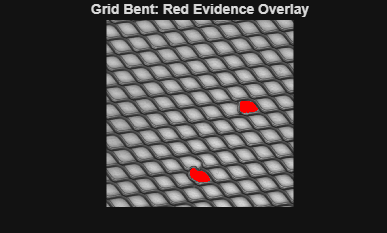

% Import image
gr_threadImg = imread(".\mvtec_anomaly_detection_USED_v4\grid\FAIL\thread\002.png");

% Display results
imshow(gr_threadImg);
title("Image Data from 002.png");

% Pass each defect label so the function selects the appropriate defect branch.
[gr_bentEvidence, gr_bentOverlay] = inspectGrid(gr_bentImg, "bent");

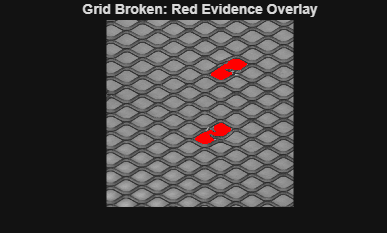

[gr_brokenEvidence, gr_brokenOverlay] = inspectGrid(gr_brokenImg, "broken");
[gr_glueEvidence, gr_glueOverlay] = inspectGrid(gr_glueImg, "glue");
[gr_metalContEvidence, gr_metalContOverlay] = inspectGrid(gr_metalContImg, "metal_contamination");
[gr_threadEvidence, gr_threadOverlay] = inspectGrid(gr_threadImg, "thread");


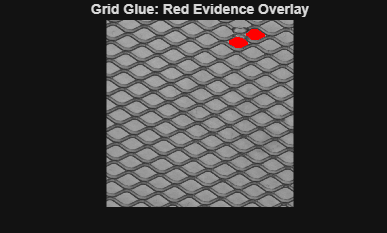

% Bent overlay.
figure;
imshow(gr_bentOverlay);
title("Grid Bent: Red Evidence Overlay");


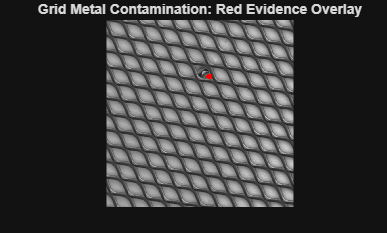

% Broken overlay.
figure;
imshow(gr_brokenOverlay);
title("Grid Broken: Red Evidence Overlay");


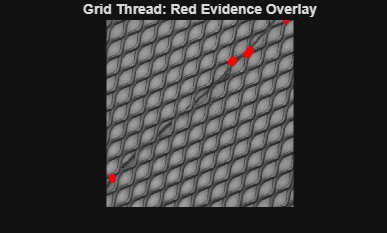

% Glue overlay.
figure;
imshow(gr_glueOverlay);
title("Grid Glue: Red Evidence Overlay");


% Metal_contamination overlay.
figure;


Grid bent metrics:


imshow(gr_metalContOverlay);

Number of suspicious regions: 2


title("Grid Metal Contamination: Red Evidence Overlay");

Size of largest suspicious region: 5651 pixels


Area ratio: 0.0104


% Thread overlay.
figure;


Grid broken metrics:


imshow(gr_threadOverlay);

Number of suspicious regions: 2


title("Grid Thread: Red Evidence Overlay");

Size of largest suspicious region: 10731 pixels


Area ratio: 0.0199


fprintf("\nGrid bent metrics:\n");
fprintf("Number of suspicious regions: %d\n", gr_bentEvidence.numComponents);


Grid glue metrics:


fprintf("Size of largest suspicious region: %d pixels\n", gr_bentEvidence.maxArea);

Number of suspicious regions: 2


fprintf("Area ratio: %.4f\n", gr_bentEvidence.areaRatio);

Size of largest suspicious region: 4522 pixels


Area ratio: 0.0086


fprintf("\nGrid broken metrics:\n");
fprintf("Number of suspicious regions: %d\n", gr_brokenEvidence.numComponents);


Grid metal contamination metrics:


fprintf("Size of largest suspicious region: %d pixels\n", gr_brokenEvidence.maxArea);

Number of suspicious regions: 1


fprintf("Area ratio: %.4f\n", gr_brokenEvidence.areaRatio);

Size of largest suspicious region: 723 pixels


Area ratio: 0.0007


fprintf("\nGrid glue metrics:\n");
fprintf("Number of suspicious regions: %d\n", gr_glueEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", gr_glueEvidence.maxArea);
fprintf("Area ratio: %.4f\n", gr_glueEvidence.areaRatio);

fprintf("\nGrid metal contamination metrics:\n");
fprintf("Number of suspicious regions: %d\n", gr_metalContEvidence.numComponents);
fprintf("Size of largest suspicious region: %d pixels\n", gr_metalContEvidence.maxArea);
fprintf("Area ratio: %.4f\n", gr_metalContEvidence.areaRatio);

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

Your goal in this step is to use a MathWorks provided pretrained network (recommended: `resnet18`) to classify each part as either a PASS or FAIL, that will be part of the output of the function you began to build in the previous step.

- Load the recommended starter network: use `imagePretrainedNetwork` and select `resnet18` from the Deep Learning Toolbox.

- Resize/augment input with `augmentedImageDatastore(...)` to match the network input size.

- Fine-tune the last layers for your classes (start with `PASS` vs `FAIL`), using `trainNetwork(...)` or a guided workflow such as [Get started with transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) or [pretrained network workflows](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html).

- The output of your AI classification model should be a predicted label (PASS/FAIL) and a confidence score in that label

Deliverable: `[aiLabel, aiScore] = classify(net, roiForNet)` 

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

% NOTE: resnet18 network has an image input size of 224-by-224-by-3.

% For Task 3, you need:
% An imageDatastore pointing to the original PASS and FAIL images.
% An augmentedImageDatastore that resizes/prepares those images as ResNet-18 reads them.

% Function used for classifying a SINGLE image
function [aiLabel, aiConfidence] = classifyImg(img, netObject)
    % Read in the image
    I = imread(img);

    %Use code to convert grayscale to RGB if needed
    %{
    if size(I,3) == 1
        I = repmat(I,[1 1 3]);
    end
    %}

    % Determine input size needed
    neededSize = netObject.Layers(1).InputSize(1:2);

    % Resize Image
    I = imresize(I, neededSize);

    % Convert image to array format for network
    IArray = dlarray(single(I), "SSCB");

    % Obtain scores
    aiScores = minibatchpredict(netObject, IArray);

    % Use if needed to convert to MATLAB array
    %{
    aiScoresPart = extractdata(aiScoresPart);
    %}

    % Find highest score for label output
    [aiConfidence, idx] = max(aiScores);

    % Obtain label
    aiLabel = netObject.Classes(idx);
end

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

Your image inspection function (e.g. `inspectPar(I)`) should combine the classical evidence with the AI classification output. 

In other words, your image inspection function should integrate both classical evidence from image processing and an AI classification decision. The AI classifier provides the main decision (PASS/FAIL) while the classical evidence extraction provides interpretability, traceability, and sanity checks for that decision.

Your function should return:

- `finalLabel` (from AI, in Task 3)

- `confidenceScore` (from AI, in Task 3)

- `evidenceOverlay` (from Step 4 in Task 2)

- `evidenceMetrics` (from Step 5 in Task 2)

- (optional) `baselineDecision` and a “disagreement flag” if optional rules in Step 6 from Task 2 and AI output disagree

Optionally, you can also choose to overlay these results on the image using `insertShape(...)` / `insertText(...)`, and save rejects with `imwrite(...)`

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

% DELIVERABLE
function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics] = inspectPart(I, inspectionStruc)

    
    % Classify part type
    [partLabel partConfidence] = classifyImg(I, inspectionStruc.PartClassifier)

    % Classify condition (pass/fail)
    [finalLabel confidenceScore] = classifyImg(I, inspectionStruc.ConditionClassifiers.(string(partLabel)))

    % Classify defect type
    [typeLabel typeConfidence] = classifyImg(I, inspectionStruc.DefectTypeClassifiers.(string(partLabel)))

    % Determine function to run
if lower(string(finalLabel)) == "fail"

        % Run the matching classical image-processing function.

        switch lower(string(partLabel))

            case "hazelnut"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectHazelnut(I, typeLabel);

            case "wood"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectWood(I, typeLabel);

            case "bottle"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectBottle(I);

            case "grid"
                [evidenceMetrics, evidenceOverlay] = inspectGrid(I, typeLabel);

            otherwise
                error("Unsupported part type: %s", string(partLabel));
        end

else

    % No defect evidence is needed for a passing image.
    evidenceOverlay = I;

    evidenceMetrics.numComponents = 0;
    evidenceMetrics.maxArea = 0;
    evidenceMetrics.areaRatio = 0;

end
end

% Test function on image for correct output

% Import One Test Image:
% --> Set the imported image variable name to: img

% Import image
img = imread(".\mvtec_anomaly_detection_USED_v4\hazelnut\FAIL\crack\000.png");

% Display results
imshow(img);
title("Image Data from 000.png");

[aiLabel, aiScore, evidence, metrics] = inspectPart(img, InspectionSystem);

% Display for finalLabel = PASS:
if lower(string(aiLabel)) == "pass"
    % Display the original passing image.
    figure;
    imshow(evidence);

    title(sprintf("Final Label: %s", string(aiLabel)));
    fprintf("\nInspection result:\n");
    fprintf("Final label: %s\n", string(aiLabel));
    fprintf("Confidence score: %.2f%%\n", aiScore * 100);


    % Display for finalLabel = FAIL:
else
    % Display the defect evidence overlay.
    figure;
    imshow(evidence);
    title(sprintf("Final Label: %s", string(aiLabel)));

    % Display results only for failed parts.
    fprintf("Final label: %s\n", string(aiLabel));
    fprintf("Confidence Score: %.2f%%\n", aiScore * 100);
    fprintf("Number of suspicious regions: %d\n", metrics.numComponents);
    fprintf("Largest suspicious region: %d pixels\n", metrics.maxArea);
    fprintf("Area ratio: %.4f\n", metrics.areaRatio);
end

## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.





## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

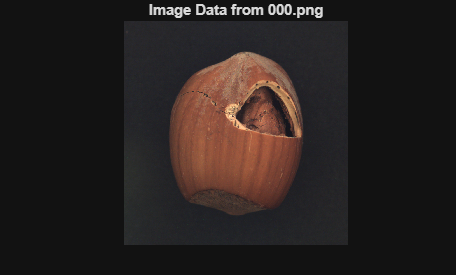

Unrecognized function or variable 'InspectionSystem'.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?